# Actividad 1 (Velocidades Lineares y Angulares)

Alan Iván Flores Juárez | A01736001

En esta actividad se debe obtener el vector de velocidad lineal y angular de la siguiente configuración:

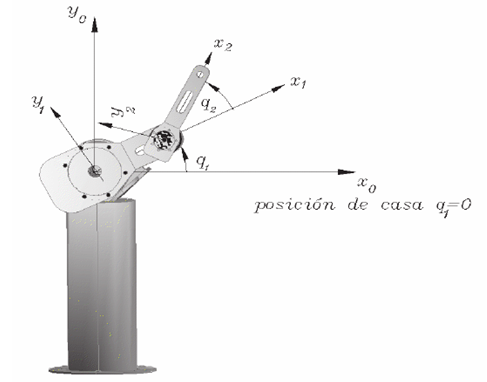

Este robot consta de dos grados de libertad de eje rotacional, como se puede observar en la imagen.

clear all
clc

%Declaración de variables simbólicas (No tienen un valor específico)
syms th1(t) th2(t) l1 l2 t  

## Etapa 1 (grados de libertad)

En esta sección de código declaramos que se trata de un robot de dos ejes de libertad de junta rotacional. Esto dentro de la variable RP.

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0];

De igual manera se declara el ángulo que poseen ambos ejes, esto dentro del vector de coordenadas articulares.

%Creamos el vector de coordenadas articulares
Q= [th1 th2];
disp('Coordenadas articulares');

Coordenadas articulares


pretty (Q);

(th1(t), th2(t))



%Creamos el vector de velocidades articulares
Qp= diff(Q, t); %Utilizo diff para derivadas cuya variable de referencia no depende de otra: ejemplo el tiempo
disp('Velocidades articulares');

Velocidades articulares


pretty (Qp);

/  d          d        \
| -- th1(t), -- th2(t) |
\ dt         dt        /



%Número de grado de libertad del robot
GDL= size(RP,2); %***Siempre se coloca 2, ya que indica la dimensión de las columnas
GDL_str= num2str(GDL);%Convertimos el valor numérico a una cadena de carácteres tipo string


%Articulación 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [l1*cos(th1);
           l1*sin(th1);
                     0];%*** Vector de posición indexado por página

%Matriz de rotación de la articulación 1 respecto a 0
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];

%Articulación 2
%Posición de la junta 2 respecto de 0

En este apartado se toma en cuenta la longitud de tanto la primera articulación y su ángulo como la de la segunda para poder determinar la posición del segundo eje respecto de el punto de referencia.

P(:,:,2)=[l1*cos(th1)+l2*cos(th1+th2); 
          l1*sin(th1)+l2*sin(th1+th2);
          0];

%Matriz de rotación de la articulación 2 respecto a 0
R(:,:,2)=[cos(th2) -sin(th2) 0; ...
          sin(th2) cos(th2)  0;
          0         0        1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

## Etapa 2 (Transformaciones homogéneas)

En esta sección se realizan las transformaciones homogéneas, tanto de la forma local, así como de la forma global, para esto se requiere de la matriz de rotación definida por la matriz R, el vector de traslación definido por el vector P, el vector de ceros dada por Vector_ceros y por último el escalar.

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);%****

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);%*****

%Inicializamos los vectores de posición vistos desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL);

En la siguiente sección de código se realiza la transformación de las matrices locales a las matrices globales para cada uno de los ángulos de libertad

for i = 1:GDL
    i_str= num2str(i);
    %Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]); %Matriz de transformación homogénea local
    pretty (A(:,:,i)); %Simplifica el resultado

    %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i); %Obtiene la matriz de transformación homogénea global a partir de la local
    catch
       T(:,:,i)= A(:,:,i);  %Caso específico cuando i=1 nos marcaría error en try
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i)); %Simplifica la matriz de transfromación global
    pretty(T(:,:,i));
    %Obtenemos la matriz de rotación RO y el vector de translación PO de la matriz de transformación Homogénea global T(:,:,GDL)
    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %Simplifican ambas matrices
    pretty(RO(:,:,i)); 
    pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



/ l1 cos(th1(t)) \
|                |
| l1 sin(th1(t)) |
|                |
\        0       /



Matriz de Transformación local A2


/ cos(th2(t)), -sin(th2(t)), 0, l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)) \
|                                                                        |
| sin(th2(t)),  cos(th2(t)), 0, l1 sin(th1(t)) + l2 sin(th1(t) + th2(t)) |
|                                                                        |
|      0,            0,      1,                     0                    |
|                                                                        |
\      0,            0,      0,                     1                    /



Matriz de Transformación global T2


/ #3, -#2, 0, l1 cos(th1(t)) + l1 cos(2 th1(t)) + l2 cos(#1) \
|                                                            |
| #2,  #3, 0, l1 sin(th1(t)) + l1 sin(2 th1(t)) + l2 sin(#1) |
|                                                            |
|  0,  0,  1,                        0                       |
|                                                            |
\  0,  0,  0,                        1                       /

where

   #1 == 2 th1(t) + th2(t)

   #2 == sin(th1(t) + th2(t))

   #3 == cos(th1(t) + th2(t))




/ cos(th1(t) + th2(t)), -sin(th1(t) + th2(t)), 0 \
|                                                |
| sin(th1(t) + th2(t)),  cos(th1(t) + th2(t)), 0 |
|                                                |
\           0,                    0,           1 /



/ l1 cos(th1(t)) + l1 cos(2 th1(t)) + l2 cos(2 th1(t) + th2(t)) \
|                                                               |
| l1 sin(th1(t)) + l1 sin(2 th1(t)) + l2 sin(2 th1(t) + th2(t)) |
|                                                               |
\                               0                               /



Dado que poseemos de dos grados de libertad, obtenemos dos matrices de transformación locales y globales, esto se entiende ya que i recorre GDL, es decir el número de grados de libertad. Una vez con la matriz de transformación global, podemos obtener la matriz de rotación RO y el vector de traslación PO de nuestra matriz de transformación homogénea global para cada uno de nuestros grados de libertad.

## Etapa 3 (Jacobiano)

En esta sección de código se realizan las operaciones necesarias para calcular el jacobiano lineal y angular de forma analítica, primero se revisa el tipo de articulación del robot, para determinar la ecuación a utilizar, de misma froma se revisan los casos base para ambos tipos de articulaciones, obteniendo la matriz identidad para ambos casos.

%Calculamos el jacobiano lineal y angular de forma analítica
%Inicializamos jacobianos analíticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if ((RP(k)==0)|(RP(k)==1))%Casos: articulación rotacional y prismática

       %Para las articulaciones rotacionales
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));%*****
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL)); %Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
        %Para las articulaciones prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
        end
            Jw_a(:,k)=[0,0,0];
     end
end
%Simplifican los jacobianos lineales y angulares
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ - l1 sin(th1(t)) - l1 sin(2 th1(t)) - #1, - l1 sin(2 th1(t)) - #1 \
|                                                                   |
|  l1 cos(th1(t)) + l1 cos(2 th1(t)) + #2,   l1 cos(2 th1(t)) + #2  |
|                                                                   |
\                     0,                               0            /

where

   #1 == l2 sin(2 th1(t) + th2(t))

   #2 == l2 cos(2 th1(t) + th2(t))




Es así como obtenemos el jacobiano de froma analítica, con el resultado mostrado en la matriz de jacobiano lineal. En este caso la interpretación de los resultados es debido a que nuestro robot experimenta movimiento traslacional tanto en los ejes 'x' y 'y' y no en el eje 'z', ya que en este experimenta un movimiento rotacional.

disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0 \
|      |
| 0, 0 |
|      |
\ 1, 1 /



De igual manera se obtiene el jacobiano angular de forma analítica, desplegada en la anterior matriz. El resultado obtenido se argumenta ya que el robot y sus ejes no experimentan un movimiento rotacional en los ejes 'x' y 'y', mientras que sí lo hace en el eje 'z'.

## Etapa 4 (Velocidades)

**Velocidad lineal**

En esta última etapa se obtiene la velocidad lineal, al multiplicar la derivada Qp por el valor obtenido en el jacobiano lineal, resultando en la matriz de velocidades lineales que se muestra a continuación.

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/ - #4 (#2 + l2 sin(#1)) - #5 (l1 sin(th1(t)) + #2 + l2 sin(#1)) \
|                                                                |
|  #4 (#3 + l2 cos(#1)) + #5 (l1 cos(th1(t)) + #3 + l2 cos(#1))  |
|                                                                |
\                                0                               /

where

   #1 == 2 th1(t) + th2(t)

   #2 == l1 sin(2 th1(t))

   #3 == l1 cos(2 th1(t))

         _________
          d
   #4 == -- th2(t)
         dt

         _________
          d
   #5 == -- th1(t)
         dt




De misma forma el resultado se explica por los mismos motivos del jacobiano lineal, ya que el robot experimenta velocidad lineal únicamente en el eje 'x' y 'y'. Y no lo hace en el eje de las 'z'.

**Velocidad angular**

De igual forma obtenemos la velocidad angular al multiplicar el jacobiano ángular obtenido por la derivada Qp, resultando en el vector de velocidades angulares mostrado.

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/           0           \
|                       |
|           0           |
|                       |
| _________   _________ |
|  d           d        |
| -- th1(t) + -- th2(t) |
\ dt          dt        /



Podemos concluir que las velocidades angulares obtenidas son correctas ya que dado que la rotación de las articulaciones de nuestro robot, estan dadas únicamente en el eje de las 'Z', mientras que su velocidad angular en el eje 'x' y 'y' se mantiene en cero.